## **数据说明 ⭐⭐⭐**

% Polyhedron 数据类型：
%   X.A X.b 可以输出
%   创建方式1: X = Polyhedron(A,b);
%   创建方式2: X = Polyhedron('lb',...,'ub',...);
%   创建方式3: X = Polyhedron(X_vertx); 其中 X_vertex = [1,1;1,-1;-1,1;-1,-1] 一个正方形
%                                       使用 X_vertex = [-1;1] 会创建一条线
%   X.computeV
%   X.V         可以直接查看多面形顶点坐标
%   X.plot      可以直接画图
% 
% polytope 数据类型
%   X.A X.b 不能输出
%   [A,b] = double(X) 可以达到 X.A, X.b 的效果
%   创建方式: X = polytope(A,b);
%   polytope 属性更多
%   X.plot   不能画图

## **系统参数**

close all; clear; clc;

A = [1 0.0999;
     0 0.9976];

% A = [1 0.1;
%      0 1];   % 这个系统没有 Invariant Set 因为矩阵特征值 = 1，通过矢量场也能看出来，
%                                                           % 最大不变集是过原点的水平线

B = -[0.0083;
      0.1665];

%%%%%%%%%%%%%%%%%%%%%%%%%
alpha = pi/6; 
beta  = 0.8;
A = [cos(alpha) sin(alpha); 
    -sin(alpha) cos(alpha)]*beta;
B = [0.5;
     0.5];
%%%%%%%%%%%%%%%%%%%%%%%%%

Q_e   = eye(size(A));
R_e   = 0.1;

Q_MPC = eye(size(A));
R_MPC = 0.1;

Q_f   = eye(size(A));
R_f   = 1;

% 帮助文档
help LTISystem

  Object representation of an LTI system
 
  To create an LTI object out of a state-space object:
    s = LTISystem(ss)
 
  To import data from sysStruct/probStruct:
    s = LTISystem(sysStruct, probStruct)

    LTISystem 的文档



% 创建系统
sys = LTISystem('A',A,'B',B);

Ax = [cos(pi/3)  sin(pi/3); 
     -cos(pi/3) -sin(pi/3);
	  sin(pi/3) -cos(pi/3); 
     -sin(pi/3)  cos(pi/3)];
bx = [2;1;2;5];
Au = [1;-1]; bu = [0.5;0.5];

X = Polyhedron(Ax,bx);
U = Polyhedron(Au,bu);

sys.x.with('setConstraint'); sys.x.setConstraint = X;
sys.u.with('setConstraint'); sys.u.setConstraint = U;


% 计算 Set
sys.x.penalty = QuadFunction(Q_f);
sys.u.penalty = QuadFunction(R_f);

Invariant_Set     = sys.invariantSet;            % 计算 Control Invariant Set

Iteration 1...
Iteration 2...
Iteration 3...


Invariant_Set_LQR = sys.LQRSet;                  % 计算 Invariant Set (LQR 控制器)

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


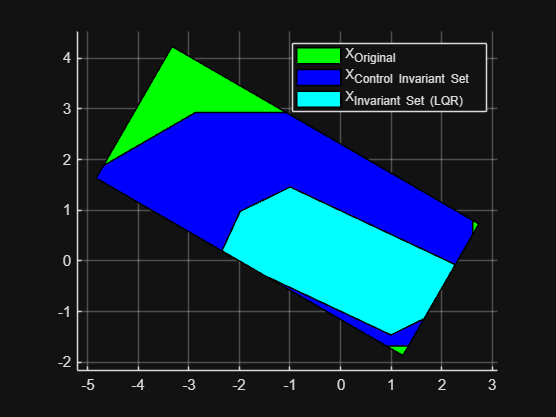


% 画图
figure; axis equal; hold on;
X.plot('color','g','alpha',1.0)                  % 绘制 X
Invariant_Set.plot('color','b','alpha',1.0);     % 绘制 Xf_      x = (A)x  
Invariant_Set_LQR.plot('color','c','alpha',1.0); % 绘制 Xf_LQR   x = (A-BK)x
legend('X_{Original}','X_{Control Invariant Set}','X_{Invariant Set (LQR)}')
hold off;

% 绘制矢量场
K = dlqr(A,B,Q_f,R_f);
addpath('Function')
figure; hold on; axis equal; grid on;
X.plot('color','g','alpha',1.0)                  % 绘制 X
Invariant_Set.plot('color','b','alpha',1.0);     % 绘制 Xf_      x = (A)x  
% Plot_Vector_Field(A-B*K,[-5,3],[-2,4]);
Plot_Vector_Field(A,[-5,3],[-2,4]);
hold off;

## 创建控制器

clc; close all; clear;

% 系统参数
A = [1 1;
     0 1];

B = [1;
     0.5];

Q_f = eye(size(A));
R_f = 1;

Q_e   = eye(size(A));
R_e   = 0.1;

Q_MPC = eye(size(A));
R_MPC = 0.1;

Q_f   = eye(size(A));
R_f   = 1;

% 创建系统
sys = LTISystem('A',A,'B',B);
% sys.x.min = [-5; -2];   sys.x.max = [5; 2];    % 设置 X state constraint
% sys.u.min = [-1.00];    sys.u.max = [1.00];    % 设置 U input constraint
sys.x.min = [-4.7; -1.72];  sys.x.max = [4.72; 1.72];    % 设置 XT state constraint
sys.u.min = [-0.77];    sys.u.max = [0.77];              % 设置 UT input constraint
sys.x.penalty = QuadFunction(Q_f);               % 设置 Q_f
sys.u.penalty = QuadFunction(R_f);               % 设置 R_f

% 计算 terminal set
Xf_mpt = sys.LQRSet;                             % Polyhedron

Iteration 1...
Iteration 2...
Iteration 3...
Iteration 4...


% Xf_mpt.plot

% 设置 terminal cost + terminal constraint
sys.x.with('terminalPenalty');
sys.x.terminalPenalty = QuadFunction(Q_f);
sys.x.with('terminalSet');
sys.x.terminalSet = Xf_mpt;

% MPC 控制器
controller = MPCController(sys, 10);

% 生成 eMPC 控制器
empc = controller.toExplicit();

mpt_plcp: 39 regions


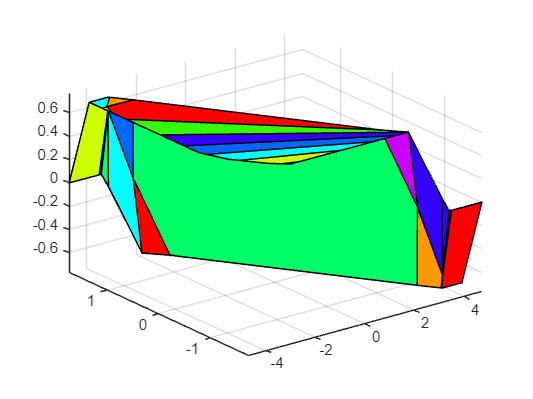

empc.feedback.fplot()


empc.evaluate([3;0])

ans = -0.7700